# `AYUDANTÍA 3 Josefa Barraza M.`

A = load('mataveriPREP9999.dat');  % cargar base de datos.
A = errorNaN(A); % apliquen su función de transformar -9999 a NaN.
B = dos_col(A);  % apliquen su función de transformar a 2 columnas.

% Obtener info por separado
year = B(:,1);
data = B(:,2);

#### VERSIÓN 1

% Inicializar el vector de medias móviles y de cada uno: OPCIONAL
% media_movil = zeros(length(datos) - ventana + 1, 1); 
% media_movil=[]

ventana = 13 ; % cantidad de datos para calcular la media movil
% Calcular estad móviles

for i = 1:(length(data) - ventana + 1)
    media_m(i) = mean(data(i:i+ventana-1), 'omitnan'); % promedio
    std_m(i) = std(data(i:i+ventana-1), 'omitnan'); % desv. estándar
    var_m(i) = var(data(i:i+ventana-1), 'omitnan'); % varianza

    q1_m(i) = quantile(data(i:i+ventana-1), 0.25);
    q2_m(i) = quantile(data(i:i+ventana-1), 0.5);  % Mediana o Q2
    q3_m(i) = quantile(data(i:i+ventana-1), 0.75);
    q4_m(i) = quantile(data(i:i+ventana-1), 1);

    P20_m(i) = prctile(data(i:i+ventana-1), 20);
    P40_m(i) = prctile(data(i:i+ventana-1), 40);
    P60_m(i) = prctile(data(i:i+ventana-1), 60);
    P80_m(i) = prctile(data(i:i+ventana-1), 80);
end
trim_m = (q1_m + 2.*q2_m + q3_m)/3 ;


Parte del 1 hasta el valor del largo de datos menos la ventana + 1, por ejemplo, en cado de tener ventana 13, se parte del 1 a (492 - 13 + 1) = 


% Transpuesta (:,1)
media_m = media_m' ;
std_m = std_m';
var_m = var_m';
q1_m = q1_m';
q2_m = q2_m';
q3_m = q3_m';
q4_m =q4_m';
P20_m = P20_m';
P40_m = P40_m';
P60_m = P60_m';
P80_m = P80_m';
trim_m = trim_m';


### VERSIÓN 2: SCARLETT

% 2da forma de sacar M.M y D.E.M
% esta es mejor
tiempomovil=[];
meanmovil=[];
stdmovil=[];

c=0  ; % contador
w=13 ; % es el tamaño de cada media movil

for i=w:1:length(data)
    c=c+1;
    meanmovil(c)=mean(data(i-(w-1):i));
    stdmovil(c)=std(data(i-(w-1):i));
    tiempomovil(c)=mean(year(i-(w-1):i));

    q1m(c+1)=prctile(data(i-w+1:i),25);  
    me(c+1)=median(data(i-w+1:i)); % mediana movil
    q3m(c+1)=prctile(data(i-w+1:i),75);
end

% (data(i-w+1:i), es similar!

***Como funciona este ciclo for:***  si w=25, tenemos que primero, el contador parte del dato 1, luego calcula la media.

 El primer valor que toma i es i=w,25...   (x(25-25+1:25)) = (x(1:25)), es decir que saca la media desde el dato 1 al dato 25.

 segundo dato: i=26     (x(26-25+1:26)) = (x(2:26)), es decir, le saca la media desde el dato 2 al 26, y así sucesivamente.

Para graficar necesitamos tener el tiempo movil, que es lo mismo que la media movil pero al plotearlo le sacamos la media movil a la columna con los años y no con los valores. 

Datos que se pierden en la media movil:

vector de largo n , ancho de ventana w

Al calcular la media movil del vector n, *¿cuántos datos se pierden?*...  **n-(w-1)**

Ejemplo: si n=100, w=10  --> 100-(10-1) = vector nuevo de 91 datos.

### VERSIÓN 3: SCARLETT


%% 3era forma de sacar M.M y D.E.M y general
function[mediamovil,years,desvmovil]=mmvl(year,data,n,p)

%year=años; y=datos; n=cantidad de años por media movil
%p=paso que sigue

vector1=[];
vector2=[];
vector3=[];

for i=0:p:lenght(data)
    if (i+n)<=length(data)
        vector1=[vector1;nanmean(data(i+1:i+n))];%media movil
        vector2=[vector2;nanmean(year(i+1:i+n))];%tiempo medio
        vector3=[vector3;nanstd(data(i+1:i+n))];%std medio
    else
        break
    end
end
mediamovil=vector1;
years=vector2;
stdmovil=vector3;
end 

### VERSIÓN MATLAB

prom_m = movmean(data, ventana, 'omitnan');
desv_m = movstd(data, ventana, 'omitnan');
v_m = movvar(data, ventana, 'omitnan');


SÓLO ESTÁN LAS DE ESTOS 3 ESTADÍSTICOS, POR LO QUE ES NECESARIO HACER FUNCTION PARA LOS OTROS ESTADÍSTICOS.

## Graficar

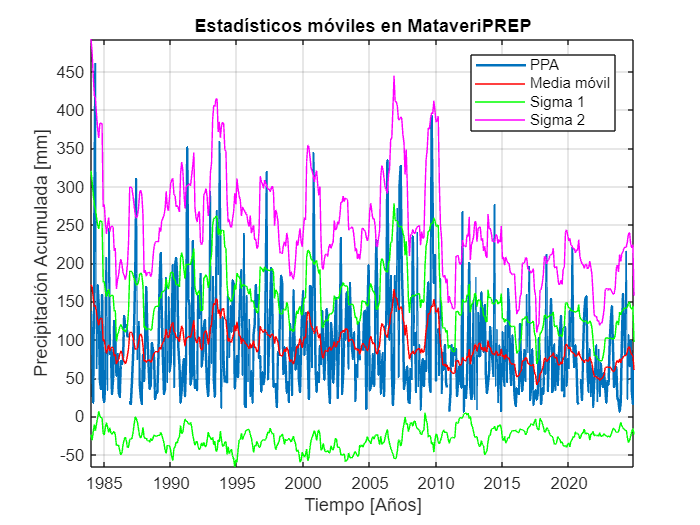

figure()
hold on
plot(year, data, LineWidth=1.5)
plot(year, prom_m,'r')
plot(year, desv_m + prom_m, 'g')
plot(year, desv_m - prom_m, 'g')
plot(year, desv_m + 2.*prom_m, 'm')
grid on; box on;
axis tight
legend('PPA', 'Media móvil', 'Sigma 1', '', 'Sigma 2', 'Location','best')
ylabel('Precipitación Acumulada [mm]')
xlabel('Tiempo [Años]')
title('Estadísticos móviles en MataveriPREP')